# Train a *k*-Means Clustering Algorithm

Cluster data using *k*-means clustering, then plot the cluster regions.

Load Fisher's iris data set. Use the petal lengths and widths as predictors.

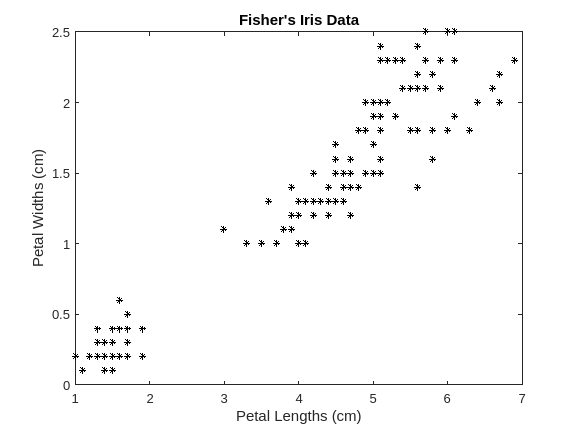

load fisheriris
X = meas(:,3:4);

figure;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)'; 
ylabel 'Petal Widths (cm)';

The larger cluster seems to be split into a lower variance region and a higher variance region. This might indicate that the larger cluster is two, overlapping clusters.

Cluster the data. Specify *k* = 3 clusters.

rng(1); % For reproducibility
[idx,C] = kmeans(X,3);

`idx` is a vector of predicted cluster indices corresponding to the observations in `X`.  `C` is a 3-by-2 matrix containing the final centroid locations. 

Use `kmeans` to compute the distance from each centroid to points on a grid. To do this, pass the centroids (`C`) and points on a grid to `kmeans`, and implement one iteration of the algorithm.

x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

    % Assigns each node in the grid to the closest centroid

`kmeans` displays a warning stating that the algorithm did not converge, which you should expect since the software only implemented one iteration.

Plot the cluster regions.

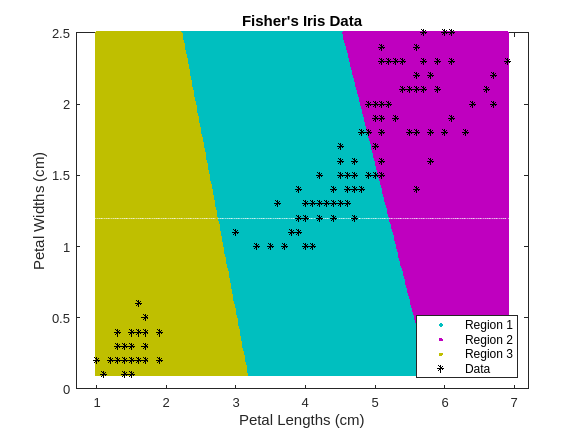

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)'; 
legend('Region 1','Region 2','Region 3','Data','Location','SouthEast');
hold off;

*Copyright 2012 The MathWorks, Inc.*